% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), filesep);
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), filesep);
% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load distance matrix
H = load('distance_matrix.mat').H;
% load the api
api = jsondecode(fileread('sql/api.json'));

% username=input('username: ', 's');
% password=input('password: ', 's');
username = 'macslab';
password = 'Ch0colate!';
db_name = 'uav2_db';
%the database connection
% conn = postgresql(username, password, "Server", 'localhost', "PortNumber", 5432, "DatabaseName", 'uav2_db');
conn = database(db_name, username, password);

% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS);
% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the tarot)
serial_number = char(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).serial_number);
serial_number = string(serial_number(1,:));
version = max(uav_tb(strcmp(uav_tb.common_name, 'tarot t18 uav'), :).version);
uav_tb = select(conn, eval(api.matlab.assets.LOAD_UAV_BY_SERIAL));

%uav_tb.escs_id = str2double(strsplit(erase(char(uav_tb.escs_id{1}), ["{", "}", "'"]), ','))
uav = load_uav(conn, serial_number, version, api);
% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;");
% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb");
group_id = group_id_tb.id(1);

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from session_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second');
% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from session_tb order by id desc limit 1;')) + 1;
if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from session_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

clear('uav_tb');

## Trajectory Generation


map = load('map.mat').map;
H = load('distance_matrix.mat').H;
all_waypoints = load('waypoints.mat').waypoints;

num_wps = 12;
velocity = 2.5; 

while true
    wpidx = randperm(length(all_waypoints), num_wps);
    s = wpidx(1);
    wpidx(1) = [];
    wp = [s];
    while ~isempty(wpidx)
        [~, idx] = sort(H(s, wpidx));
        s = wpidx(idx(1));
        wp = [wp s];
        wpidx(idx(1)) = [];
    end
    waypoints = all_waypoints(wp,:);
    waypoints(length(waypoints)+1, :) = waypoints(1,:);
    trajectory = initialize_trajectory(waypoints, velocity);
    trajectory.flight_time
    if trajectory.flight_time > 700 
        break;
    end
end

ans = 1.0527e+03

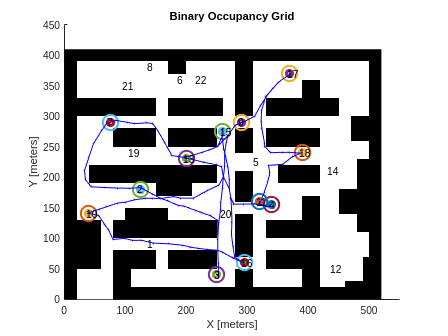


f1 = figure(1); clf;
hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'Markersize', 15, 'LineWidth', 2, 'DisplayName', sprintf("p%d", i)); 
end
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
text(all_waypoints(:,1)-5, all_waypoints(:,2), string(1:numel(all_waypoints(:,1))));
%plot(current_location(1), current_location(2), 'x', 'MarkerFaceColor', 'red', 'markersize', 17, 'LineWidth', 5, 'DisplayName', sprintf("p%d", i)); 
axis([0 550 0 450])
hold off;

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

sim_params.initial_conditions  = load('params/initial_conditions.mat').IC;
sim_params.initial_conditions.Psi = pi/2;
sim_params.initial_conditions.Z = .05;

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 3000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 10; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .05; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.15; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after %% can this even be done?
sim_params.perf_param_thresh.avg_pos_err  = 3; % this is checked after
sim_params.perf_param_thresh.max_pos_err_var  = 3; % check this (currently not used)
% sim_params.z_ref = 8;


% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;

sim_params.z_ref = sim_params.initial_conditions.z_ref;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;
if uav.battery.v0 < 4.3
    sim_params.battery_estimator.soc_ocv = interp1([sim_params.battery_estimator.soc_ocv(1) sim_params.battery_estimator.soc_ocv(end)], [3.04 4.2], sim_params.battery_estimator.soc_ocv);
end

if strcmp(uav.uav.common_name, 'default')
    sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
    sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;
end

process_type = 'degradation';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
%%%%% get the battery degradation functions
for i = 1:length(uav.battery.process_id)
    params = process_tb(process_tb.id_1 == uav.battery.process_id(i), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the motor degradation function
for j = 1:length(uav.motors)
    params = process_tb(process_tb.id_1 == uav.motors(j).process_id(1), 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.motors(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end
%%%%% get the esc failure probability function
process_type = 'failure probability';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
for j = 1:length(uav.escs)
    params = process_tb(process_tb.id_1 == uav.escs(j).process_id, 'parameters').parameters{1};
    res = jsondecode(string(params));
    uav.escs(j).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end

process_type = 'environment';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  ;
i = randi(height(process_tb));
params = process_tb(i, 'parameters').parameters{1};
res = jsondecode(string(params));
fn = fieldnames(res);
for j = 1:length(fn)
    processes.(sprintf("%s", process_type)).(sprintf("%s", process_tb(i, 'subtype').subtype{1})).(sprintf("%s", process_tb(i, 'subtype2').subtype2{1})).(sprintf("%s", fn{j})) = res.(fn{j});
end

clear('description', 'i', 'params', 'j', 'proc_tb', 'process_tb', 'process_type', 'res', 'fn');

P_failure = zeros(length(uav.escs), 1);

tic
sim('simulink/uav_simulation_tarot.slx');
toc

Elapsed time is 87.626242 seconds.


p1 =     14     9


p1 =      9    14


p1 =     32    14


p2 =     13    18


p2 =     18    13


p2 =     23    13


p3 =      4    14


p3 =     14     4


p3 =     27     4


pth =     32    14
    31    13
    31    12
    31    11
    31    10
    30     9
    29     8
    28     7
    27     6
    27     5


ans = 12.0711

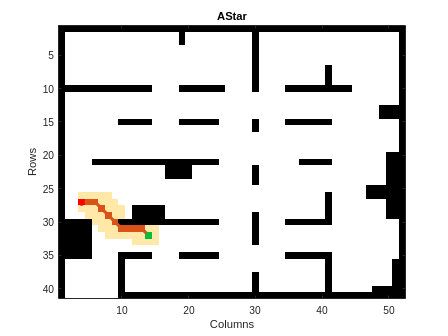


show(pln)